## ESERCIZIO I: clustering gerarchico e componenti principali

% Caricare dentro MATLAB i dati della qualità della vita delle province
% Italiane (v. file benessere.xlsx presente nella sottocartella denominata
% capComponentiPrincipali della cartella matlabMfiles).
%
% Dopo aver opportunamente trasformato i dati costruire il dendrogramma
% utilizzando il metodo del legame medio. Visualizzare il dendrogramma
% aggiungendo i nomi delle righe. Mostrare nel dendrogramma prima tutte le
% aggregazioni e poi le ultime 70 aggregazioni (utilizzando l'opzione
% 'Orientation','left'). Tagliare il dendrogramma al valore soglia di
% distanza 3.5 e attribuire ogni unità (provincia) ad un determinato gruppo
%
% Costruire il vettore colonna di lunghezza n denominato idxAndRowLabels che
% contiene l'indicazione del gruppo di appartenenza insieme al nome della
% provincia.
% Ad esempio se la prima provincia Torino è assegnata al cluster 1 il primo
% elemento di idxAndRowLabels deve contenere  '3--Torino', se la seconda
% provincia Vercelli è assegnata al gruppo 3 il secondo elemento di
% idxAndRowLabels deve contenere  '3--Vercelli',
%
% La parte di seguito è dedicata all'interpretazione dei gruppi che sono
% stati ottenuti
%
% Calcolare e mostrare la distribuzione di frequenza dei gruppi che sono stati
% ottenuti. Commentare i gruppi ottenuti.
%
% Come si interpretano i gruppi formati da una sola unità? (se ci sono)
%
% Costruire la Table denominata CentroidiT (di dimensione kx(p+2) dove k è il numero di gruppi
% trovati) che contiene nella prima colonna l'indicazione del gruppo, nella seconda
% colonna le numerosità dei gruppi, nelle colonne 3:p+2 i centroidi
% dei gruppi che sono stati trovati
% Assegnare a questa table i nomi delle righe e delle colonne appropriati
% Osservazione: centroidi dei gruppi =matrice delle medie aritmetiche
% parziali riferite ai gruppi trovati.
% Mostrare tramite disp questa table
% Confrontare il gruppo 3 con il gruppo 6
%
% Estrarre dalla table CentroidiT in una variable denominata Centroidi
% la matrice di dimensione kxp di double contenente i centroidi
%
%
% Rappresentare graficamente i dati tramite un diagramma di dispersione in
% cui i punti presentano un colore che dipende dal gruppo di appartenenza
% (suggerimento: utilizzare la funzione gscatter) e aggiungere al grafico
% le etichette del gruppo di appartenenza e del nome della provincia.
% Aggiugnere al grafico i centroidi dei gruppi con riferimento alle
% variabili in esame.
%
% Costruire il diagramma di dispersione prima con riferimento alle
% variabili 1 e 2 poi alle variabili 3 e 4 e successivamente alle variabili
% 5 e 6. Aggiungere ad ogni diagramma i centroidi con colore rosso.
% Aggiungere in ogni scatter per ogni provincia il testo contenente il nome
% Interpretare i risultati ottenuti.

% Aggiungere due caselle a discesa in modo tale che quando si fa click sul
% pulsante Hide code appaia la schermata di seguito con la possibilità di
% selezionare le variabili da utilizzare per visualizzare il diagramma di
% dispersione insieme alle etichette delle province e dei relativi
% centroidi

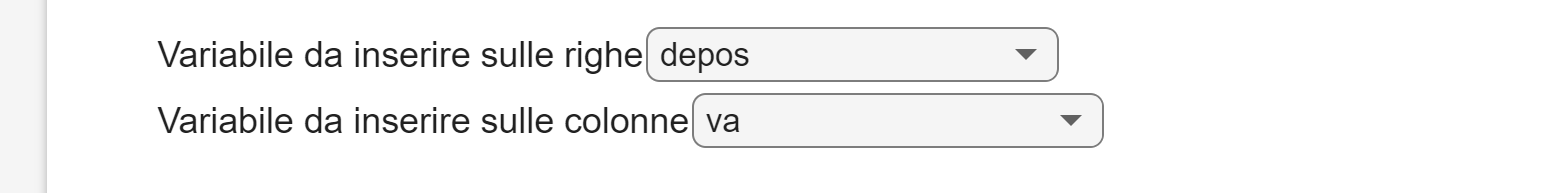

% Rappresentare i dati in termini di scatterplot matrix distinguendo per
% gruppo di appartenenza
%
% Rappresentare in coordinate parallele le province utilizzando
% un colore diverso in base al gruppo di appartenenza
% Rappresentare in coordinate parallele i centroidi
%
% Effettuare la trasformazione in termini di componenti principali non
% standardizzate (matrice ZV).
% Rappresentare gli scores (matrice ZV) delle prime due componenti
% principali con le etichette delle province e centroidi dei gruppi
% Osservazione: i centroidi dei gruppi devono essere proiettati nello
% spazio delle prime due componenti principali.
%
% Rappresentare gli score con gruppo
% di appartenenza + centroidi dei gruppi
%
% Rappresentare gli score con etichetta del nome della provincia e gruppo
% di appartenenza + centroidi dei gruppi


%% SOLUZIONE


## ESERCIZIO II: riepilogo sul clustering (gerarchico e non gerarchico)

% Caricare in memoria il dataset  crabs (granchi) tramite l'istruzione
% load crabs.mat
% (attenzione si richiede che sia stata installato
% il toolbox FSDA versione >=8.5.3)
% Questo dataset contiene 200 righe e 8 colonne.
%
% La prima colonna è la specie dei granchi.
% La seconda il sesso, la terza l'indice di riga.
% Le rimanenti colonne descrivono 5 caratteristiche morfologiche
%
% Utilizzando la funzione spmplot costruire la matrice dei diagrammi di
% dispersione delle 5 caratteristiche morfologiche, distinguendo le unità
% per specie.
% Commentare la matrice dei diagrammi di dispersione.


% Applicare alle 5 caratteristiche morfologiche
%
% 1) la metodologia di cluster gerarchico del legame singolo,
% Costuire il dendrogramma. Effettuare il taglio del dendrogramma
% utilizzando la soglia di distanza 1.8. Assegnare ogni unità ad un
% gruppo. Commentare i gruppi che sono stati trovati ed il loro
% significato (se esiste).
%
% 2) la metodologia di cluster gerarchico del legame medio. Mostrare il
% dendrogramma visualizzando tutte le aggregazione con l'opzione
% 'Orientation','right'. Colorare nel dendrogramma i rami utilizzando la
% 'ColorThreshold' di default. Quanti gruppi questa metodologia suggerisce
% se si utilizza la 'ColorThreshold' di default? Utilizzando il numero di
% gruppi suggerito dalla 'ColorThreshold' di default, assegnare ogni unità
% ad un determinato gruppo. Utilizzando la funzione spmplot, commentare ed
% interpretare i gruppi che vengono ottenuti. Illustrare se i gruppi
% trovati corrispondono alla suddivisione dei granchi nelle due specie.
% Calcolare l'indice di Rand aggiustato tra la specie la classificazione
% ottenuta. Commentare l'indice di Rand.
%
% 3) la metodologia delle k medie adattando come numero di gruppi k=2.
% Commentare i risultati ottenuti. Illustrare se i due gruppi trovati
% corrispondono alla suddivisione granchi maschi, granchi femmina.
% Utilizzando la funzione evalcluster determinare il numero ottimo di
% gruppi tramite il criterio di Calinski e Harabaz.
% Mostrare la matrice dei diagrammi di dispersione utilizzando come
% variabile di gruppi l'assegnazione ai diversi gruppi
% Calcolare l'indice di Rand aggiustato tra la specie la classificazione
% ottenuta. Commentare l'indice di Rand.

% 4) la metodologia di tclust utilizzando come numero di gruppi k=2, un
% livello di trimming pari a 0.05 (terzo argomento di input) ed imponendo
% il vincolo che il rapporto tra il massimo e il minimo autovalore delle
% matrici di covarianze non sia superiore a 1000 (quarto argomento di
% input). Calcolare l'indice di Rand aggiustato tra la specie la
% classificazione ottenuta. Commentare l'indice di Rand.



